clear;clc
A = readmatrix("data1.xlsx");
x = A(:,1);
y = A(:,2);


n = size(x, 1);
k = (n * sum(x.*y) - sum(x) * sum(y)) / (n * sum(x.*x) - sum(x) * sum(x))

k = 2.0948

b = (sum(x.*x) * sum(y) - sum(x) * sum(x.*y)) / (n * sum(x.*x) - sum(x) * sum(x))

b = -1.0548

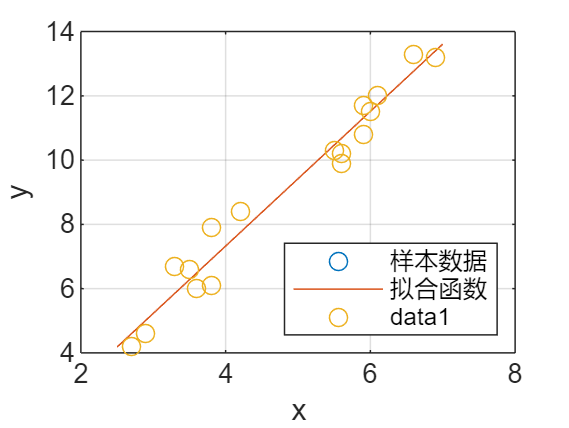

f = @(x) k * x + b;
hold on
fplot(f, [2.5, 7]);
legend('样本数据', '拟合函数', 'location', 'SouthEast')
plot(x,y,'o')
xlabel('x')
ylabel('y')
grid on

y_hat = k * x + b; % y 的拟合值
SSR = sum((y_hat - mean(y)).^2) % 回归平方和

SSR = 151.1583

SSE = sum((y_hat - y).^2) % 误差平方和

SSE = 5.7281

SST = sum((y - mean(y)).^2) % 总体平方和

SST = 156.8863

SST - SSE - SSR % 5.6843e-14 = 5.6843*10^-14 MATLAB 浮点数计算的一个误差

ans = 5.6843e-14

R_2 = SSR / SST %拟合优度越接近1越好

R_2 = 0.9635

%SST = SSE +SSR